# Sessió 7: Segmentació per Watershed amb marques

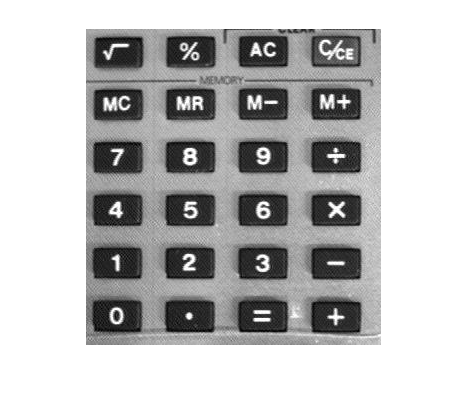

%carreguem la imatge
I = imread("calc.tif");
imshow(I)

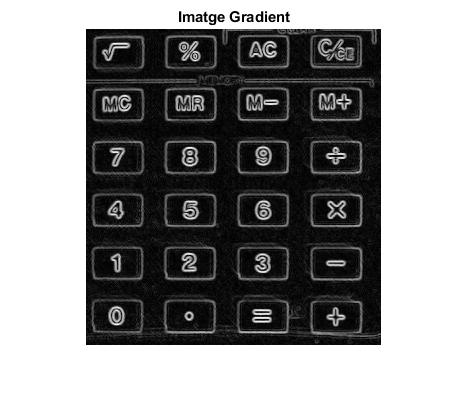

%calculem la imatge gradient que serà la funció de segmentació
gmag = imgradient(I);
imshow(gmag,[])
title('Imatge Gradient')

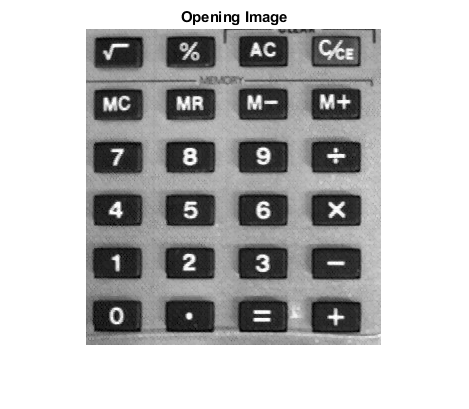

%apliquem imopen
se = strel('square',2);

Io = imopen(I,se);
imshow(Io)
title('Opening Image')

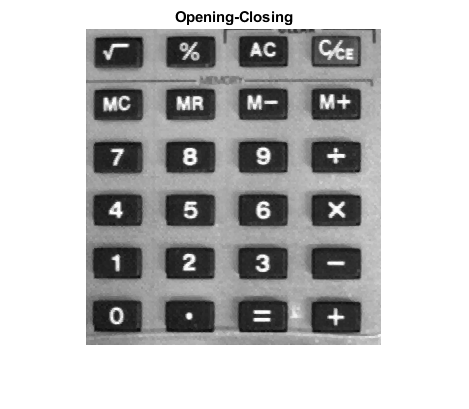

%apliquem imclose a imopen
Ioc = imclose(Io,se);
imshow(Ioc)
title('Opening-Closing')

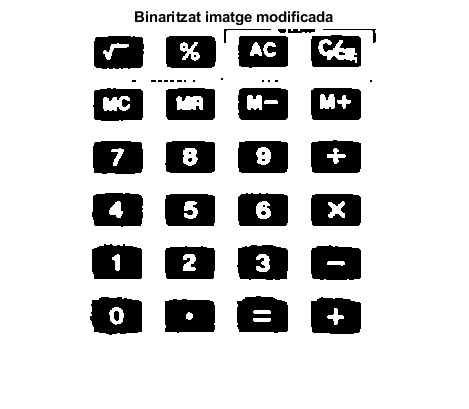

%Calculem markers del fons

%binaritzem la imatge modificada
bw = imbinarize(Ioc);
imshow(bw)
title('Binaritzat imatge modificada')

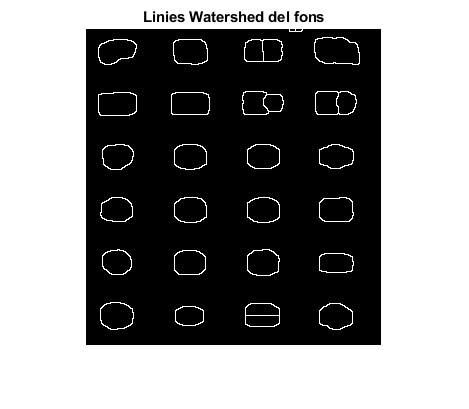


%apliquem el mètode SKIZ per separar elements del fons
D = bwdist(bw);
DL = watershed(D);
bgm = DL == 0;
imshow(bgm)
title('Linies Watershed del fons')

%Apliquem el mètode imimposemin per indicar que els minims regionals son
%només els que pertanyen al fons.
gmag2 = imimposemin(gmag, bgm);

%Posteriorment apliquem Watershed
L = watershed(gmag2);

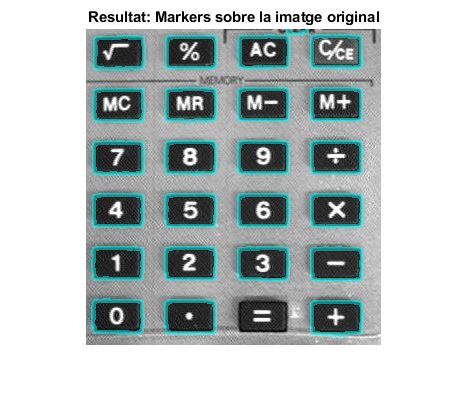

%Una manera de veure el resultat: Mostrant-lo sobre la imatge original
labels = imdilate(L==0,ones(4,4));
I4 = labeloverlay(I,labels);
imshow(I4)
title('Resultat: Markers sobre la imatge original')

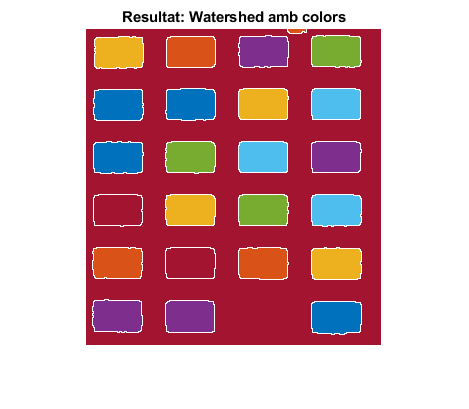


%Una altra manera de veure el resultat: Mostrant-lo com una imatge de
%colors
Lrgb = label2rgb(L,'lines','w','shuffle');
imshow(Lrgb)
title('Resultat: Watershed amb colors')